IAE = 11.7582			P = 1		I = 0.1		D = 0.5
IAE = 54.3877			P = 152.0951		I = 37.7448		D = 75.1061
IAE = 59.0886			P = 887.293		I = 102.587		D = 22.9523
IAE = 54.8749			P = 534.8213		I = 1.0818		D = 19.568
IAE = 68.683			P = 21.1438		I = 24.3103		D = 73.6683
IAE = 53.2244			P = 818.0531		I = 105.6725		D = 74.0973
IAE = 58.5741			P = 1057.0009		I = 26.166		D = 24.7953
IAE = 56.1507			P = 167.7938		I = 38.1228		D = 6.118
IAE = 52.1711			P = 973.0264		I = 41.2756		D = 62.4702
IAE = 56.3552			P = 303.4391		I = 96.0093		D = 10.4596
IAE = 66.542			P = 29.2725		I = 68.5301		D = 36.9185
IAE = 55.1348			P = 636.873		I = 97.5886		D = 35.2135
IAE = 54.873			P = 1121.8263		I = 10.3416		D = 48.4001
IAE = 65.9223			P = 923.1965		I = 23.0565		D = 10.1616
IAE = 53.8408			P = 485.7087		I = 75.5402		D = 47.9235
IAE = 65.6916			P = 861.3759		I = 7.6636		D = 10.5701
IAE = 63.1164			P = 577.5923		I = 89.1555		D = 9.2269
IAE = 54.4178			P = 529.4165		I = 72.4077		D = 35.2859
IAE = 62.5599			P = 1130.8336		I = 9

   75            2280           1.445           1.448        0
Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


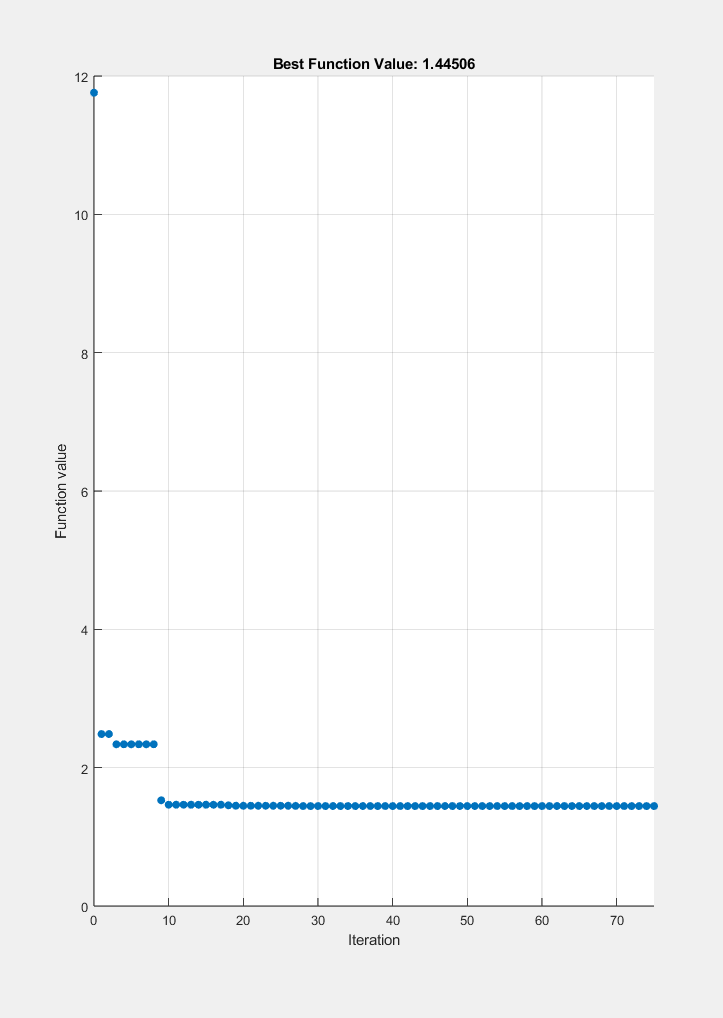

% Set nondefault solver options
options = optimoptions("particleswarm","InitialPoints",K_start,...
    "InertiaRange",Inertia_range,"SelfAdjustmentWeight",1,...
    "SocialAdjustmentWeight",3,"InitialSwarmSpan",Initial_swarm_span,...
    "MaxIterations",100,"Display","iter","PlotFcn","pswplotbestf");

% Solve
[sol,obj] = particleswarm(@tunning,numvar,lower_bounds,...
    upper_bounds,options);


% Clear variables
clearvars options